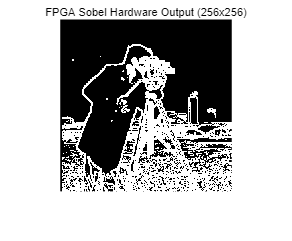

width  = 256;
height = 256;

% 1. 读取仿真输出
fid = fopen('sim_out.txt', 'r');
if fid == -1
    error('未找到 sim_out.txt，请先完成 ModelSim 仿真！');
end
raw_data = textscan(fid, '%s');
fclose(fid);

hex_str   = raw_data{1};
hex_clean = regexprep(hex_str, '[xXzZ]', '0'); % 过滤不定态
pixel_data = hex2dec(hex_clean);

% 2. 截取并重构为 256x256 图像
total_pts = min(length(pixel_data), width * height);
gray_img  = uint8(bitand(pixel_data(1:total_pts), 255));
img_mat   = reshape(gray_img, [width, height])';

% 3. 显示图像
figure('Name', 'FPGA 256x256 Sobel 边缘检测结果');
imshow(img_mat);
title('FPGA Sobel Hardware Output (256x256)');